actual = [65 48 36 24 12 6 3 1.5 8 18 30 42 54 50 43 38 31 26 23 19 13 8] * 2.54;
measured = [186 90 130 235 370 544 490 395 490 270 185 201 228 93 132 116 167 212 209 255 340 485];
values = [actual; measured];
sort(values)

ans =   165.1000   90.0000   91.4400   60.9600   30.4800   15.2400    7.6200    3.8100   20.3200   45.7200   76.2000  106.6800  137.1600   93.0000  109.2200   96.5200   78.7400   66.0400   58.4200   48.2600   33.0200   20.3200
  186.0000  121.9200  130.0000  235.0000  370.0000  544.0000  490.0000  395.0000  490.0000  270.0000  185.0000  201.0000  228.0000  127.0000  132.0000  116.0000  167.0000  212.0000  209.0000  255.0000  340.0000  485.0000



actualFiltered = actual(actual > 15 & actual < 100);
measuredFiltered = measured(actual > 15 & actual < 100)

measuredFiltered =    130   235   370   544   490   270   185   116   167   212   209   255   340   485


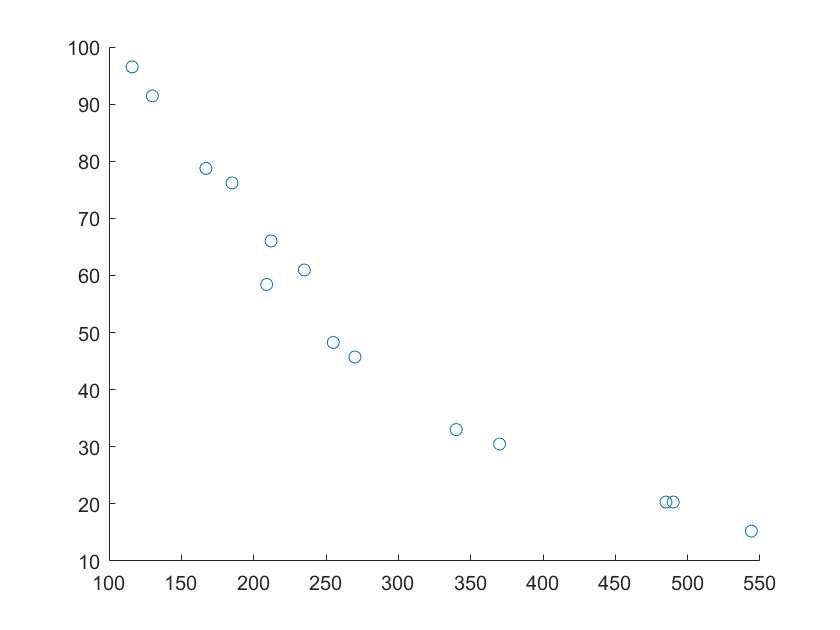

clf; hold on;
plot(measuredFiltered, actualFiltered, "o")

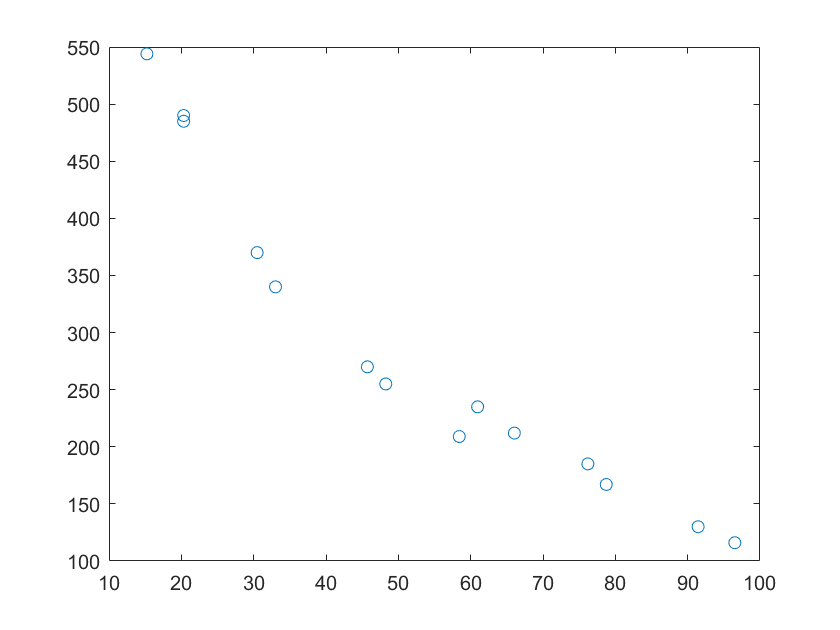

figure(); clf;
plot(actualFiltered, measuredFiltered, "o")

General model Exp2:

     f(x) = a*exp(b*x) + c*exp(d*x)

Coefficients (with 95% confidence bounds):

       a =       715.9  (568.2, 863.6)

       b =    -0.01915  (-0.02415, -0.01414)

       c =      -668.6  (-1165, -172)

       d =     -0.2333  (-0.471, 0.004446)

Goodness of fit:

  SSE: 3344

  R-square: 0.9808

  Adjusted R-square: 0.9693

  RMSE: 25.86

actual = [3 6 9 12 15 18 21 24 27 30 33] * 2.54;
measured = [445 562 492 391.5 320 287 237 205 126.5 116 93];
values = [actual; measured];
sort(values)

ans =     7.6200   15.2400   22.8600   30.4800   38.1000   45.7200   53.3400   60.9600   68.5800   76.2000   83.8200
  445.0000  562.0000  492.0000  391.5000  320.0000  287.0000  237.0000  205.0000  126.5000  116.0000   93.0000


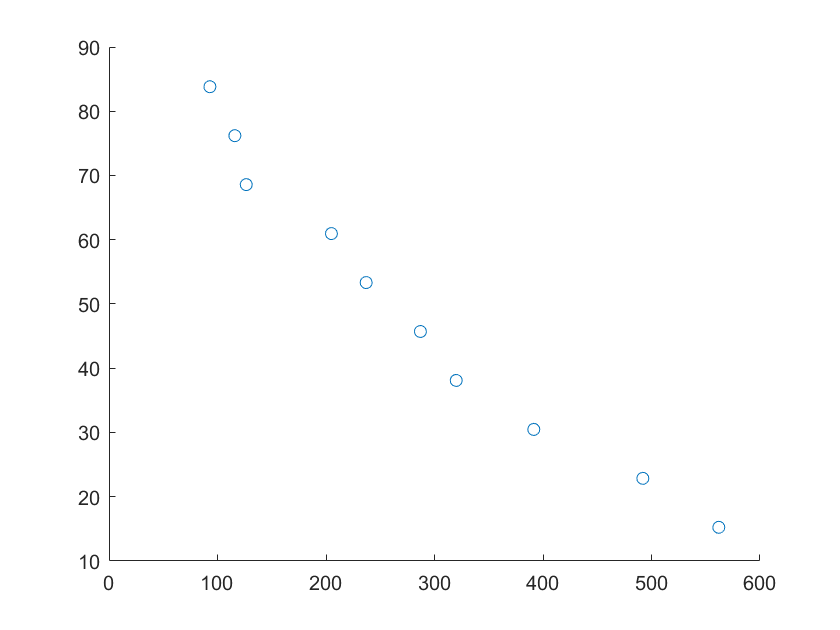


actualFiltered = actual(actual > 15 & actual < 100);
measuredFiltered = measured(actual > 15 & actual < 100);
clf; hold on;
plot(measuredFiltered, actualFiltered, "o");

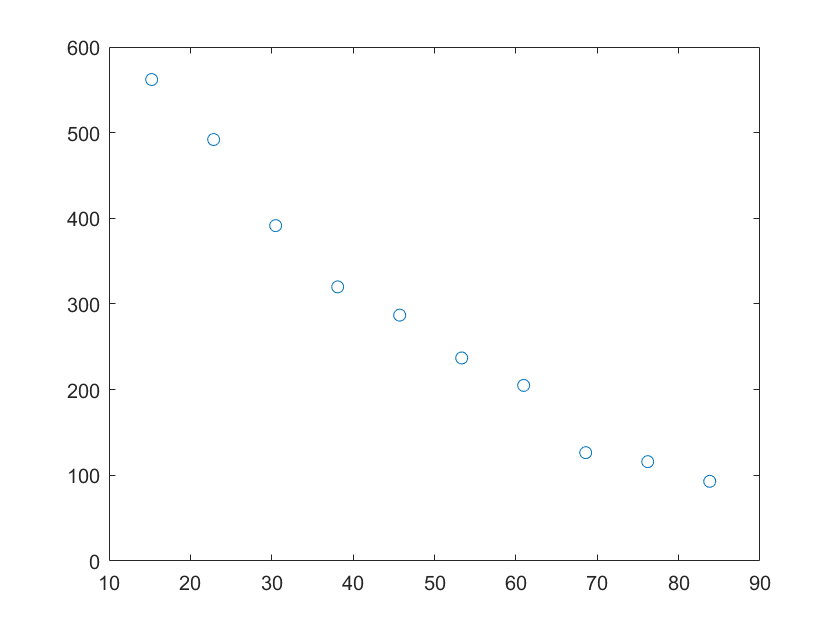

figure(); clf;
plot(actualFiltered, measuredFiltered, "o");

# Final calibration!!

% Load data
realValues = readtable("C:\Users\blan\Desktop\PIE-MiniProject2\mp2\Calibrator\calibrations\calibration3.csv");
distances = table2array(realValues(:,1));
readings = table2array(realValues(:,2));

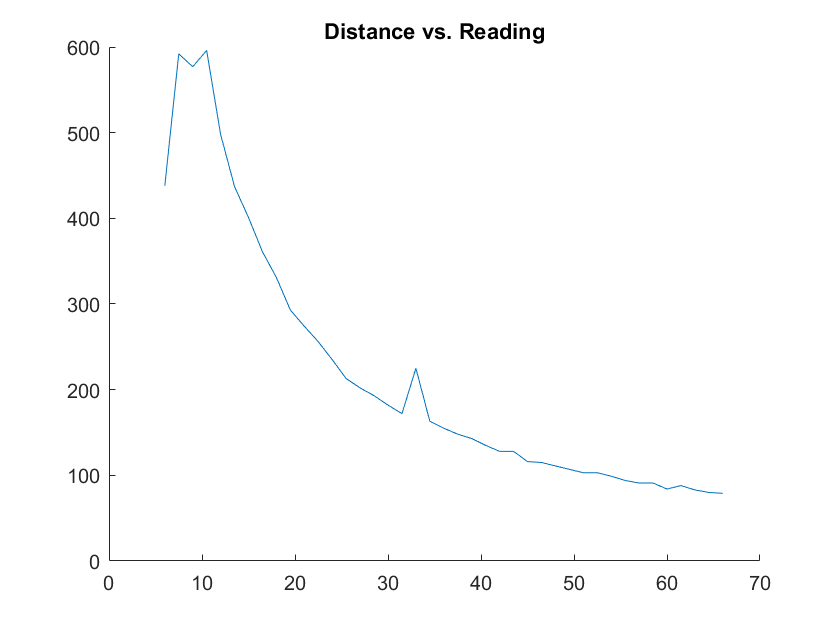

figure(); clf; hold on;
plot(distances, readings);
title("Distance vs. Reading")

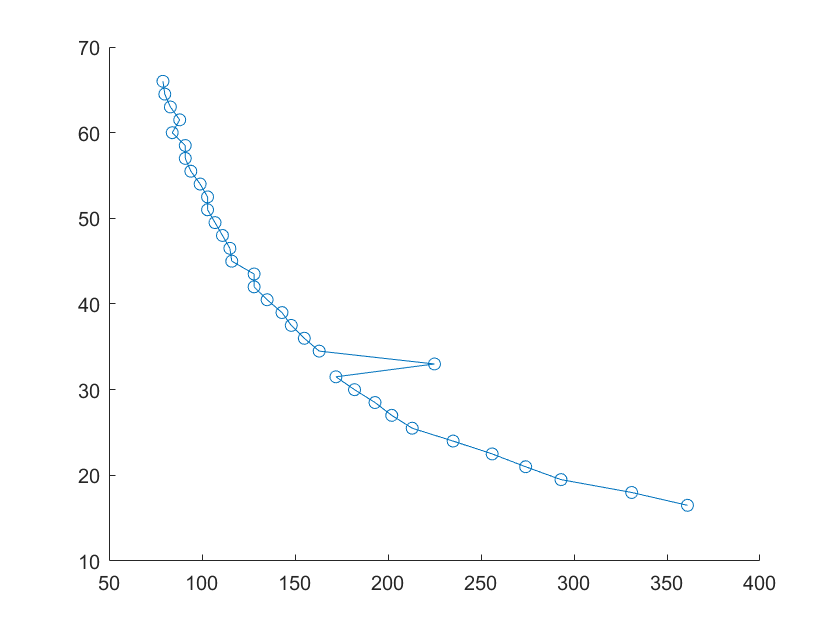

distancesFiltered = distances(distances > 15);
readingsFiltered = readings(distances > 15);
clf; hold on;
plot(readingsFiltered, distancesFiltered, "o-");

% figure(); clf;
% plot(distancesFiltered, readingsFiltered, "o-");

Remove the clear outlier at distances = 33

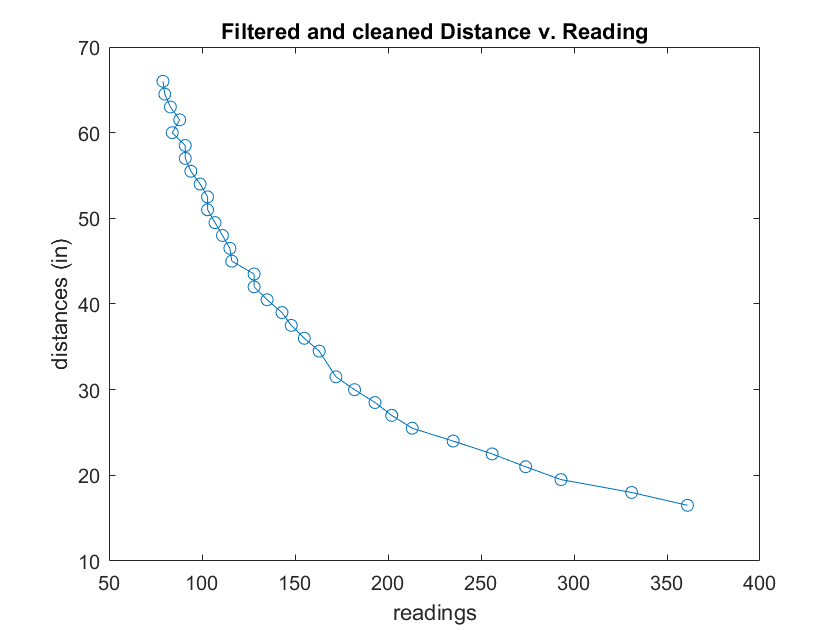

distancesFiltered = distances(distances > 15 & distances ~= 33);
readingsFiltered = readings(distances > 15 & distances ~= 33);
figure(); clf;
plot(readingsFiltered, distancesFiltered, "o-");
title("Filtered and cleaned Distance v. Reading")
xlabel("readings"); ylabel("distances (in)");

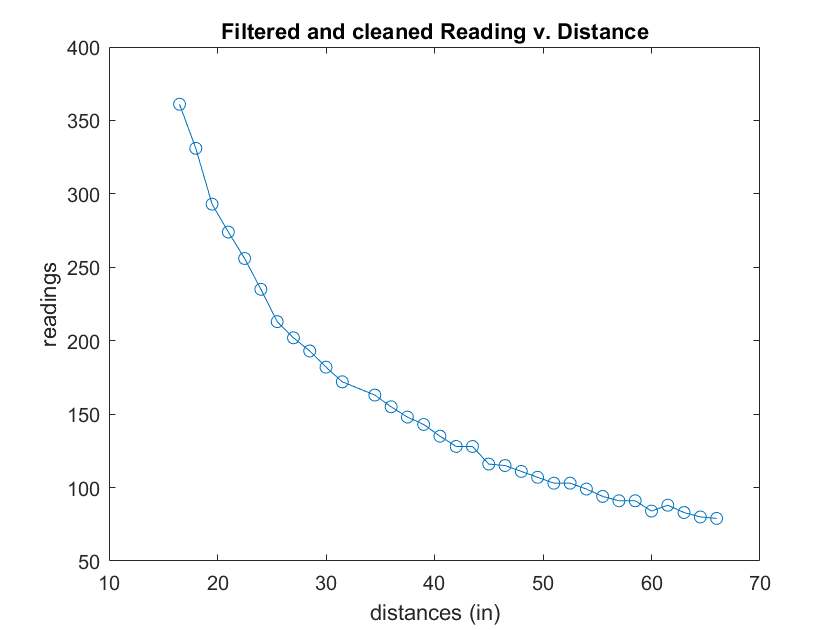


figure(); clf;
plot(distancesFiltered, readingsFiltered, "o-");
title("Filtered and cleaned Reading v. Distance")
ylabel("readings"); xlabel("distances (in)");

Error calculations

%   y = sensorValue
%   a =        7709
%   b =      -1.096
% 
% 
%   return (y / a) ** (1 / b)

a = 7709; b = -1.096;
calculated_distance = (readingsFiltered / a) .^ (1/b);

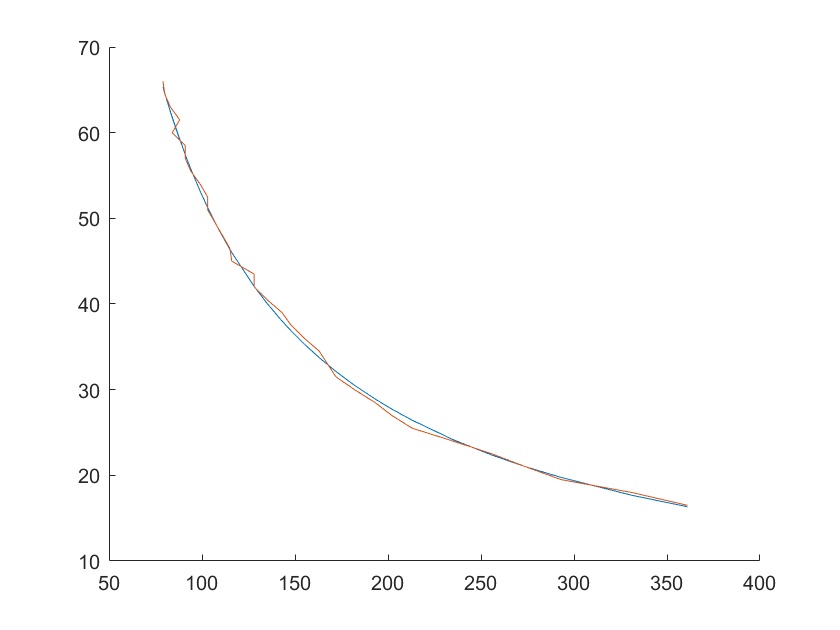

figure(); clf; hold on;
plot(readingsFiltered, calculated_distance); label1 = "Calculated distance";
plot(readingsFiltered, distancesFiltered); label2 = "Measured distance";